# Laborator 1

## Reactor chimic exoterm

Parametrii de functionare:

S = 4.28; % aria secțiunii transversale a reactorului  [m2]
d = 2.335; % diametrul bazei reactorului de formă circulară [m]
E = 49584; % energia de activare [kJ/kmol]
h = 2.335; % nivelul amestecului din reactor [m]
minusdeltaH = 24953; % entalpia de reacție [kJ/kmol]
R = 8.32; % constanta gazelor ideale [kJ/(kmol)(K)]
k0 = 34930800; % coeficient de viteză de reacție  [1/h]
rcp = 2093; % produsul dintre densitatea amestecului și căldura specifică a acestuia [kJ/(m3)(K)]
kT = 293; % coeficient de transfer termic [kJ/(m2)(K)(h)]

Pe baza acestora calculam:

V = S*h; % volumul amestecului din reactor [m3]
At = S+pi*d*h; % aria suprafeței de transfer termic a agentului de răcire [m2]
Edr = E/R;
hA = kT*At;

Valorile initiale:

ci = 10; % concentraţia molară a reactantului la intrare [kmol/m3]
q = 10; % debitul de intrare [m3/h]
Ti = 25+273; % temperatura reactantului în alimentare [K]
Tr = 25+273; % temperatura agentului de răcire [K]

Calculam punctele statice de functionare:

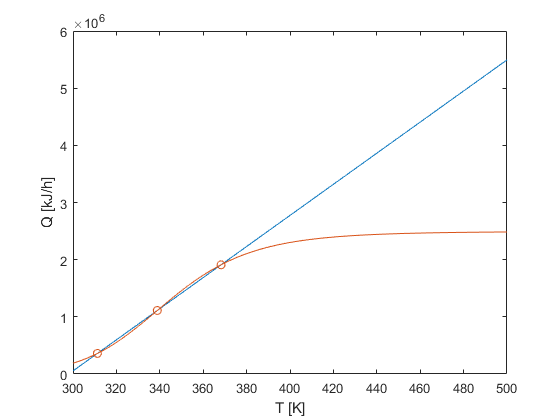

Tv = 300:0.001:500;
cx = -(rcp*q*(Ti-Tv)-kT*At*(Tv-Tr))./(minusdeltaH*V*k0*exp(-Edr./Tv));
cv = (q*ci)./(q+V*k0*exp(-Edr./Tv));
Q1 = -(rcp*q*(Ti-Tv)-kT*At*(Tv-Tr));
Q2 = minusdeltaH*V*k0*exp(-Edr./Tv).*cv;
figure(1)
plot(Tv, [Q1',Q2'],'o-','MarkerIndices',[11241 38845 68233]);
xlabel('T [K]'); ylabel('Q [kJ/h]')

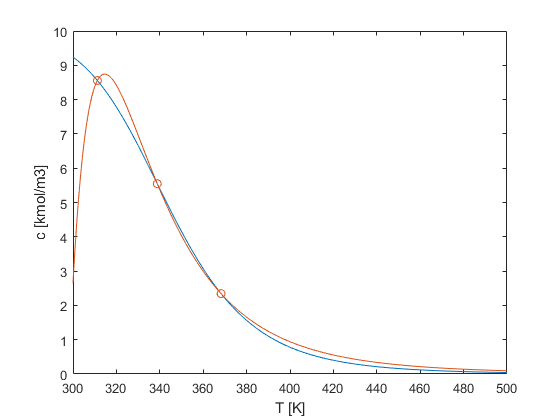

figure(2)
plot(Tv,cv,Tv,cx,'o-','MarkerIndices',[11241 38845 68233]);
xlabel('T [K]'); ylabel('c [kmol/m3]');

Punctele aproximative de echilibru stationar sunt:

P1 = [Tv(11241) cv(11241)] % P1 stabil

P1 =   311.2400    8.5566


P2 = [Tv(38845) cv(38845)] % P2 instabil

P2 =   338.8440    5.5473


P3 = [Tv(68233) cv(68233)] % P3 stabil

P3 =   368.2320    2.3436


Am ales punctul P3 pentru urmatoarele calcule:

c0 = P3(1)

c0 = 368.2320

T0 = P3(2)

T0 = 2.3436

Determinam modelul liniar in jurul unui punct de functionare:

A = zeros(2,2);
B = zeros(2,4);
C = eye(2,2);
D = zeros(2,4);

A(1,1) = -q/V-(k0*exp(-Edr/T0));
A(1,2) = -k0*exp(-Edr/T0)*Edr*c0/T0^2;
A(2,1) = (minusdeltaH/rcp)*k0*exp(-Edr/T0);
A(2,2) = -q/V-hA/(rcp*V)+minusdeltaH*k0*exp(-Edr/T0)*Edr*c0/(T0^2*rcp);

B(1,1)=(ci-c0)/V;
B(1,2)=q/V;
B(2,1)=(Ti-T0)/V;
B(2,3)=q/V;
B(2,4)=hA/rcp/V;

% Transformam spatiul starilor in functii de transfer

[NUM, DEN] = ss2tf(A,B,C,D,1);
num1 = NUM(1,1:3); num2 = NUM(2,1:3); den=DEN;
H11 = minreal(tf(num1,den))

H11 =
 
   -35.85
  ---------
  s + 1.001
 
Continuous-time transfer function.



H12 = minreal(tf(num2,den))

H12 =
 
    29.58
  ---------
  s + 1.301
 
Continuous-time transfer function.




[NUM1,DEN1] = ss2tf(A,B,C,D,2);
num1 = NUM(1,1:3); num2=NUM(2,1:3); den=DEN;
H21 = minreal(tf(num1,den))

H21 =
 
   -35.85
  ---------
  s + 1.001
 
Continuous-time transfer function.



H22 = minreal(tf(num2,den))

H22 =
 
    29.58
  ---------
  s + 1.301
 
Continuous-time transfer function.




[NUM,DEN] = ss2tf(A,B,C,D,3);
num1 = NUM(1,1:3); num2=NUM(2,1:3); den=DEN;
H31 = minreal(tf(num1,den))

H31 =
 
  0
 
Static gain.



H32 = minreal(tf(num2,den))

H32 =
 
    1.001
  ---------
  s + 1.301
 
Continuous-time transfer function.




[NUM,DEN] = ss2tf(A,B,C,D,4);
num1 = NUM(1,1:3); num2=NUM(2,1:3); den=DEN;
H41 = minreal(tf(num1,den))

H41 =
 
  0
 
Static gain.



H42 = minreal(tf(num2,den))

H42 =
 
   0.2999
  ---------
  s + 1.301
 
Continuous-time transfer function.



## Simularea dinamicii procesului in Matlab:

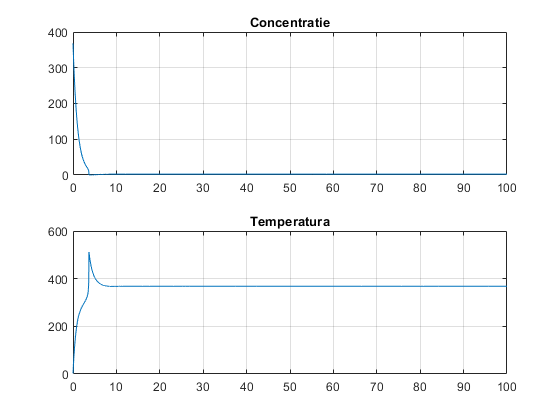

tsimulare = 0:0.01:100;
[timpsimulare, Y] = ode23(@RCCA, tsimulare, [c0;T0]);
figure(3)
subplot(2,1,1); plot(timpsimulare, Y(:,1));
title('Concentratie'); grid on;
subplot(2,1,2); plot(timpsimulare, Y(:,2));
title('Temperatura'); grid on;

## Simularea dinamicii procesului in Simulink:

Main block:

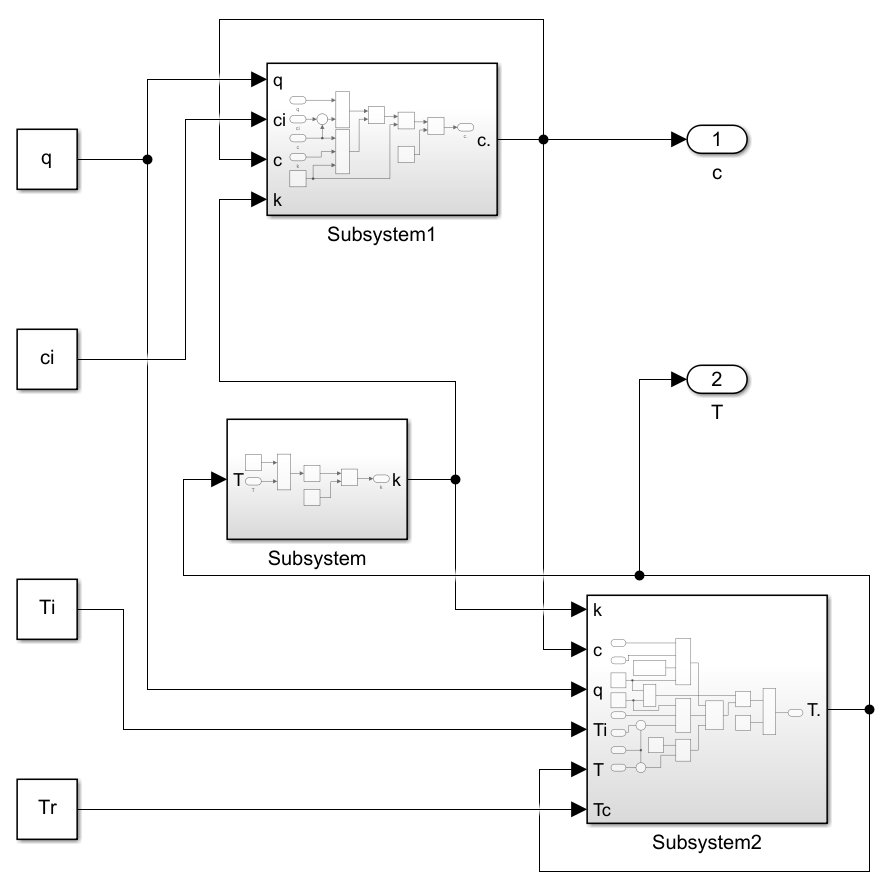

Subsystem1 block:

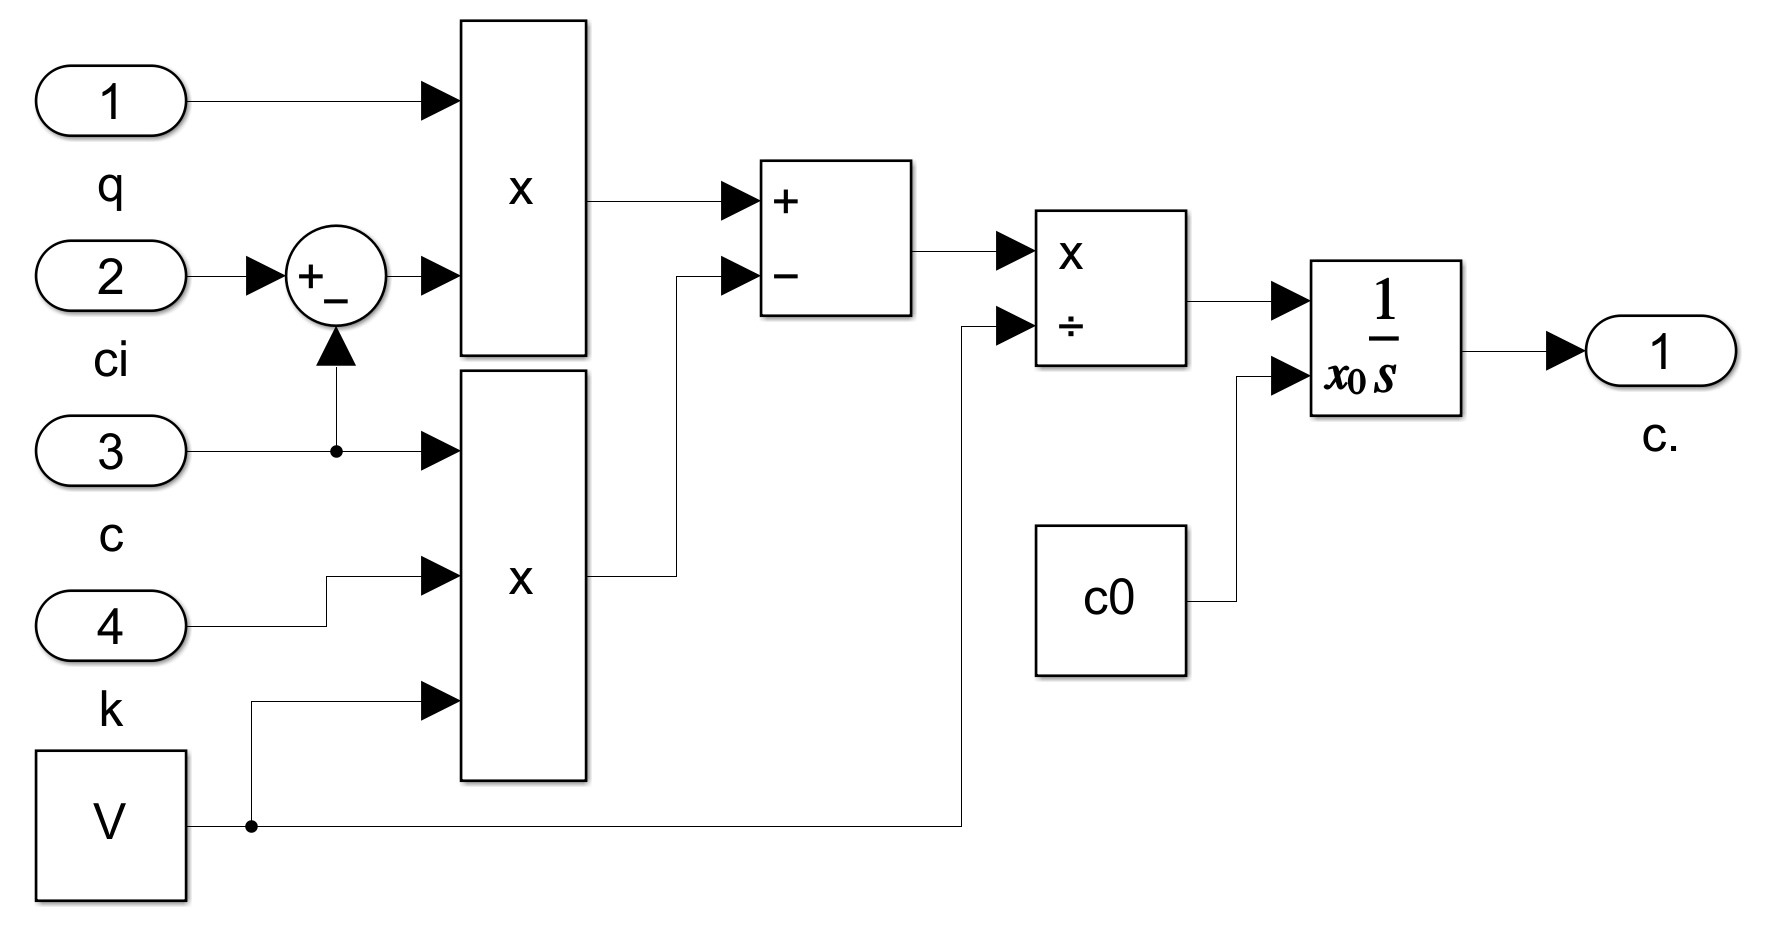

Subsystem block:

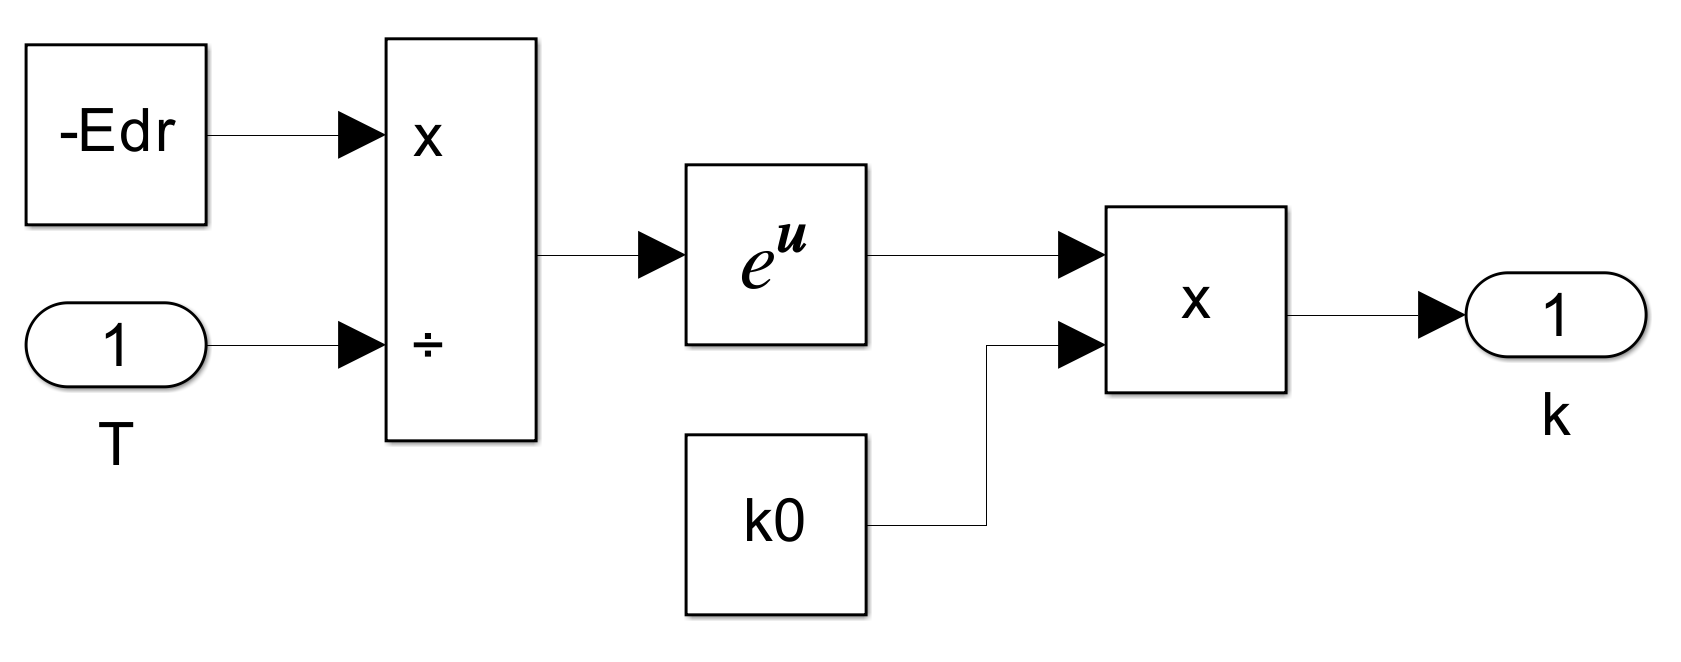

Subsystem2 block:

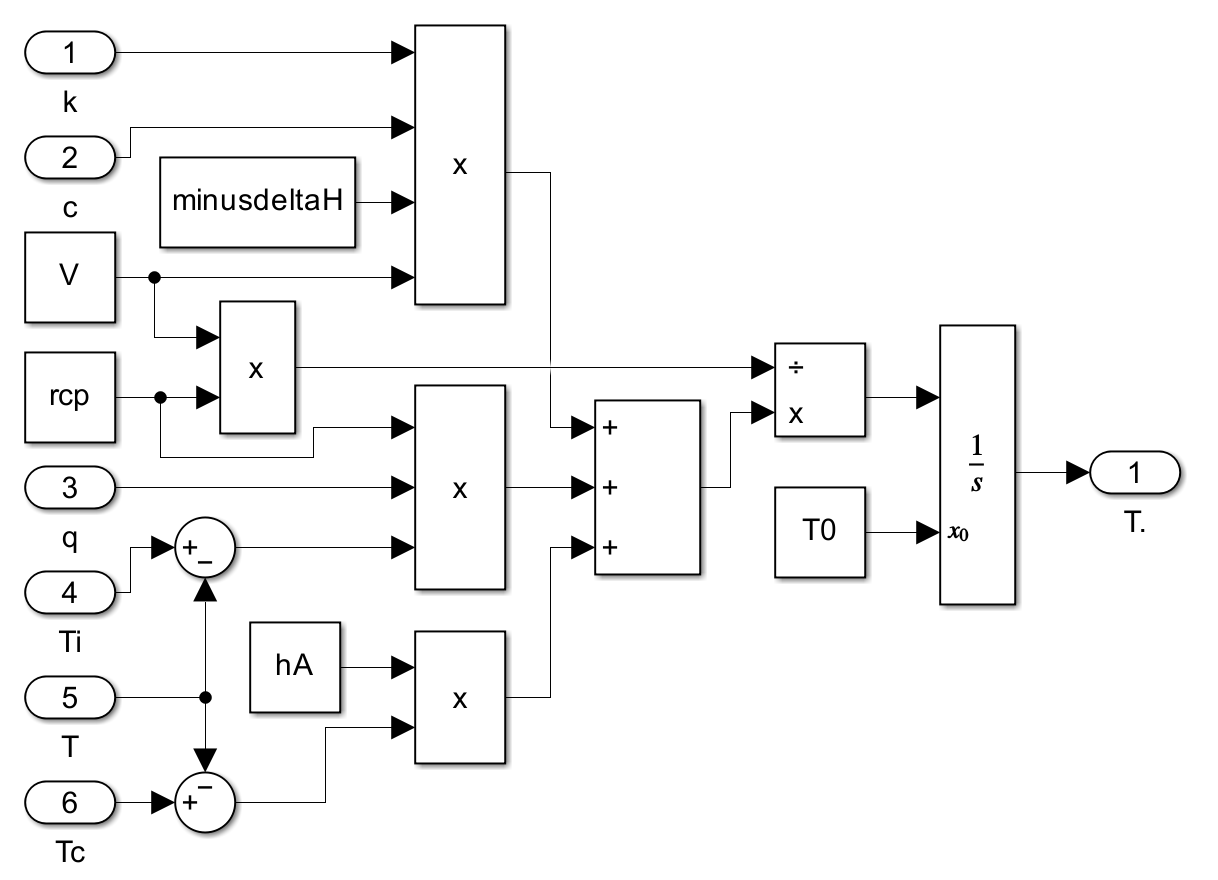

Rezultate:

Concentratie:

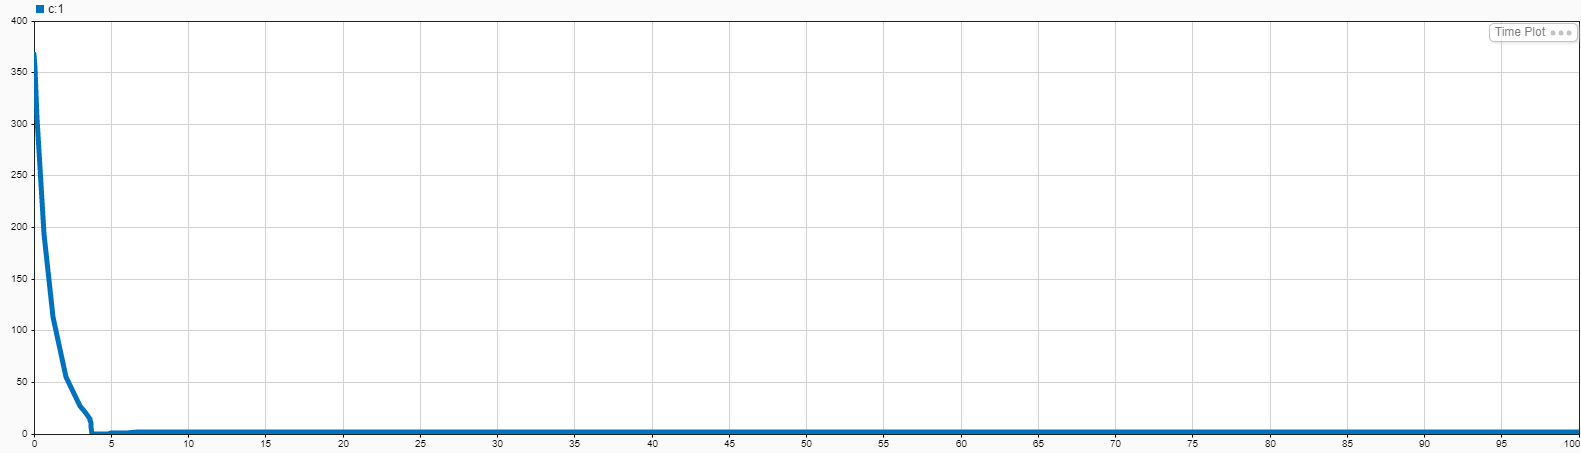

Temperatura:

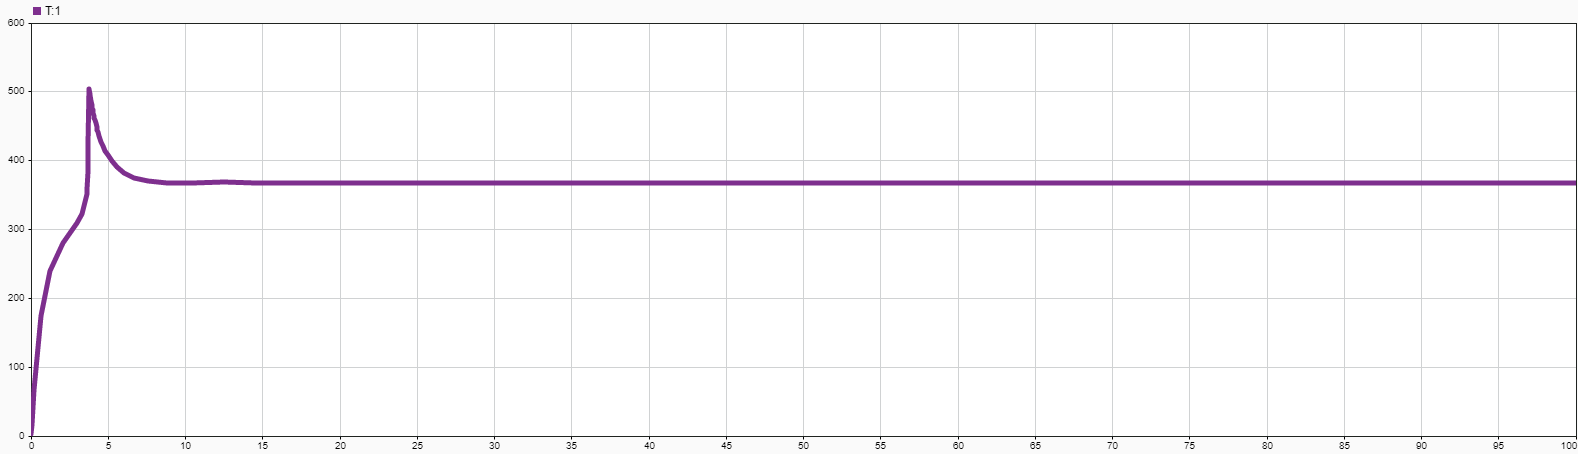

# Laborator 2

## Reactor chimic izoterm

Folosim, in principiu, parametrii de functionare folositi si in laboratorul 1.

E = 49584; % energia de activare [kJ/kmol]
h = 2.335; % nivelul amestecului din reactor [m]
R = 8.32; % constanta gazelor ideale [kJ/(kmol)(K)]
k0 = 34930800; % coeficient de viteză de reacție  [1/h]
V = 10; % volumul amestecului din reactor [m3]
At = 21.4; % aria suprafeței de transfer termic a agentului de răcire [m2]

Valorile initiale:

ci = 10; % concentraţia molară a reactantului la intrare [kmol/m3]
q = 10; % debitul de intrare [m3/h]
Ti = 25+273; % temperatura reactantului în alimentare [K]

Construim schema in simulink:

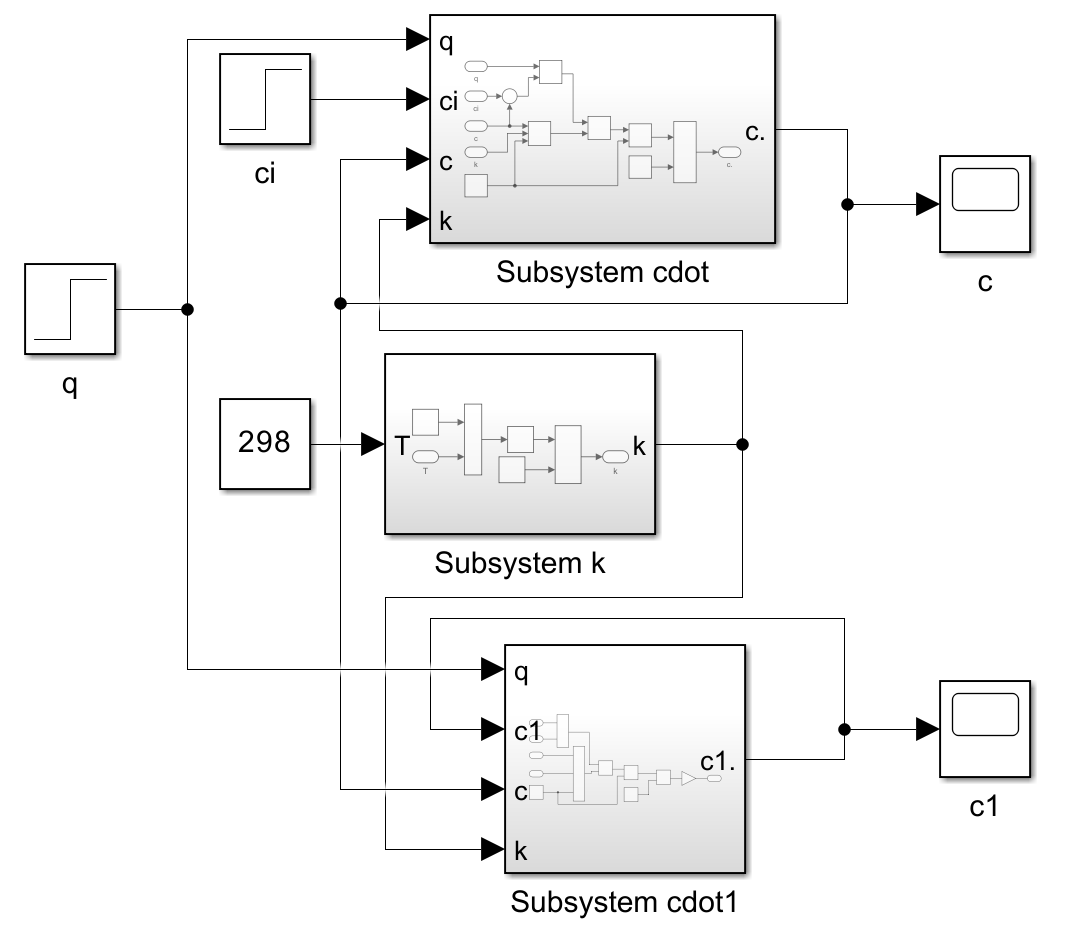

Subsystem cdot:

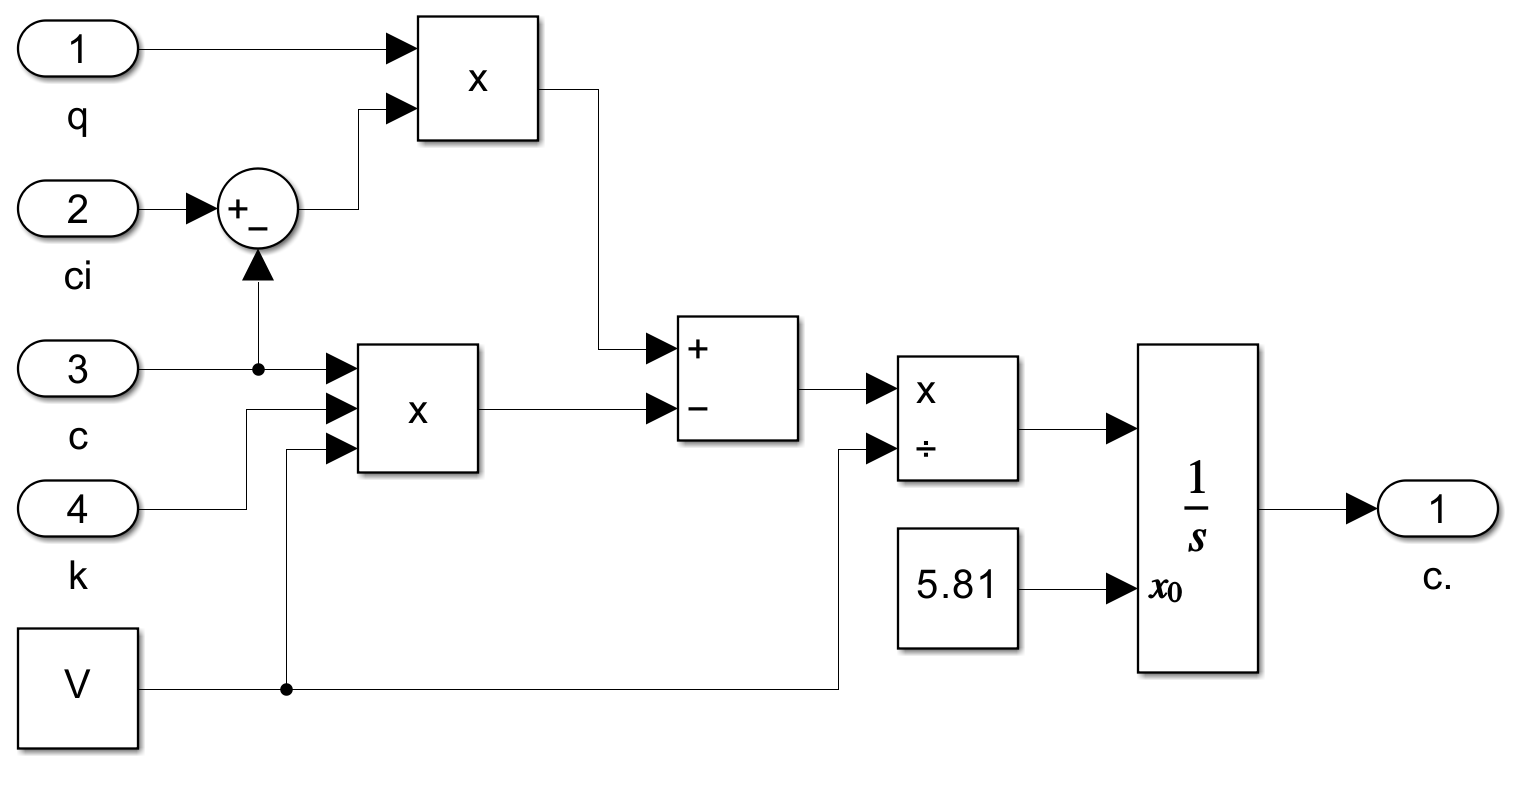

Subsystem k:

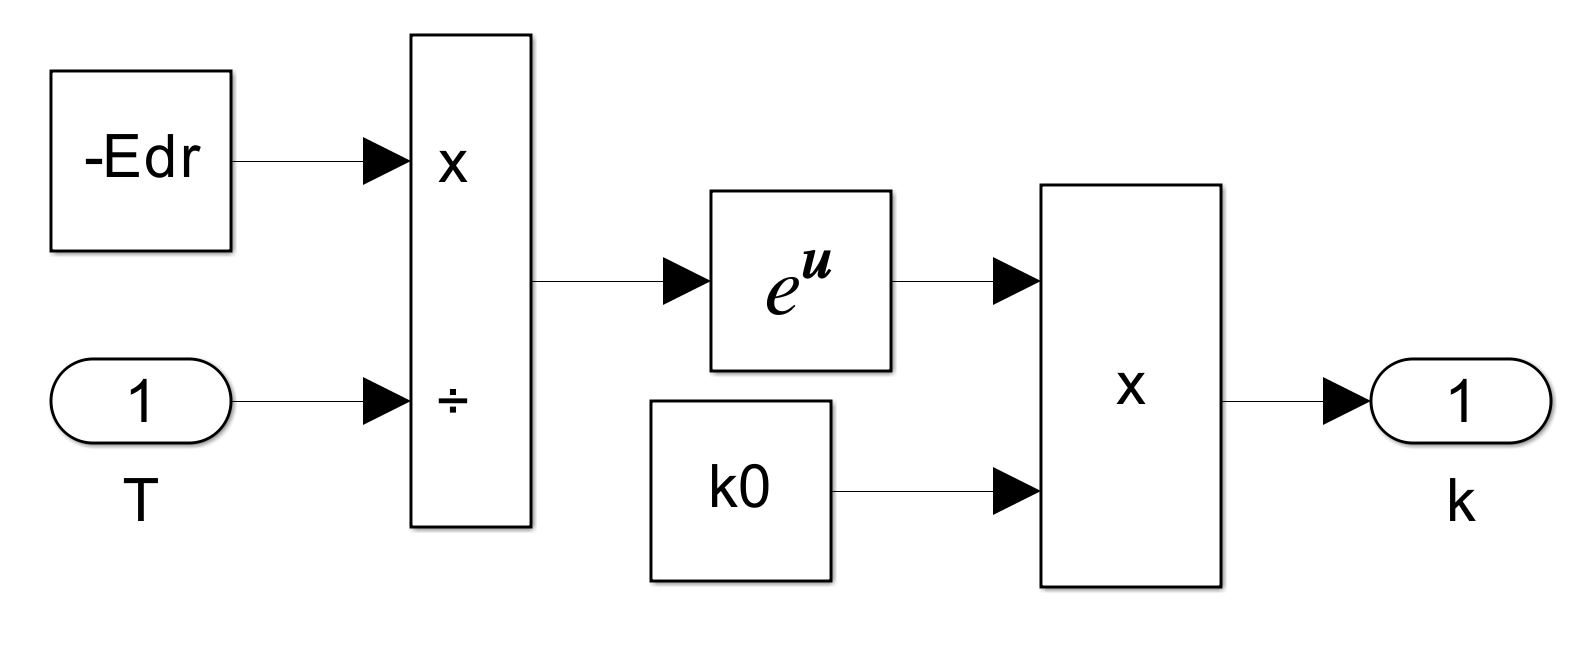

Subsystem cdot1:

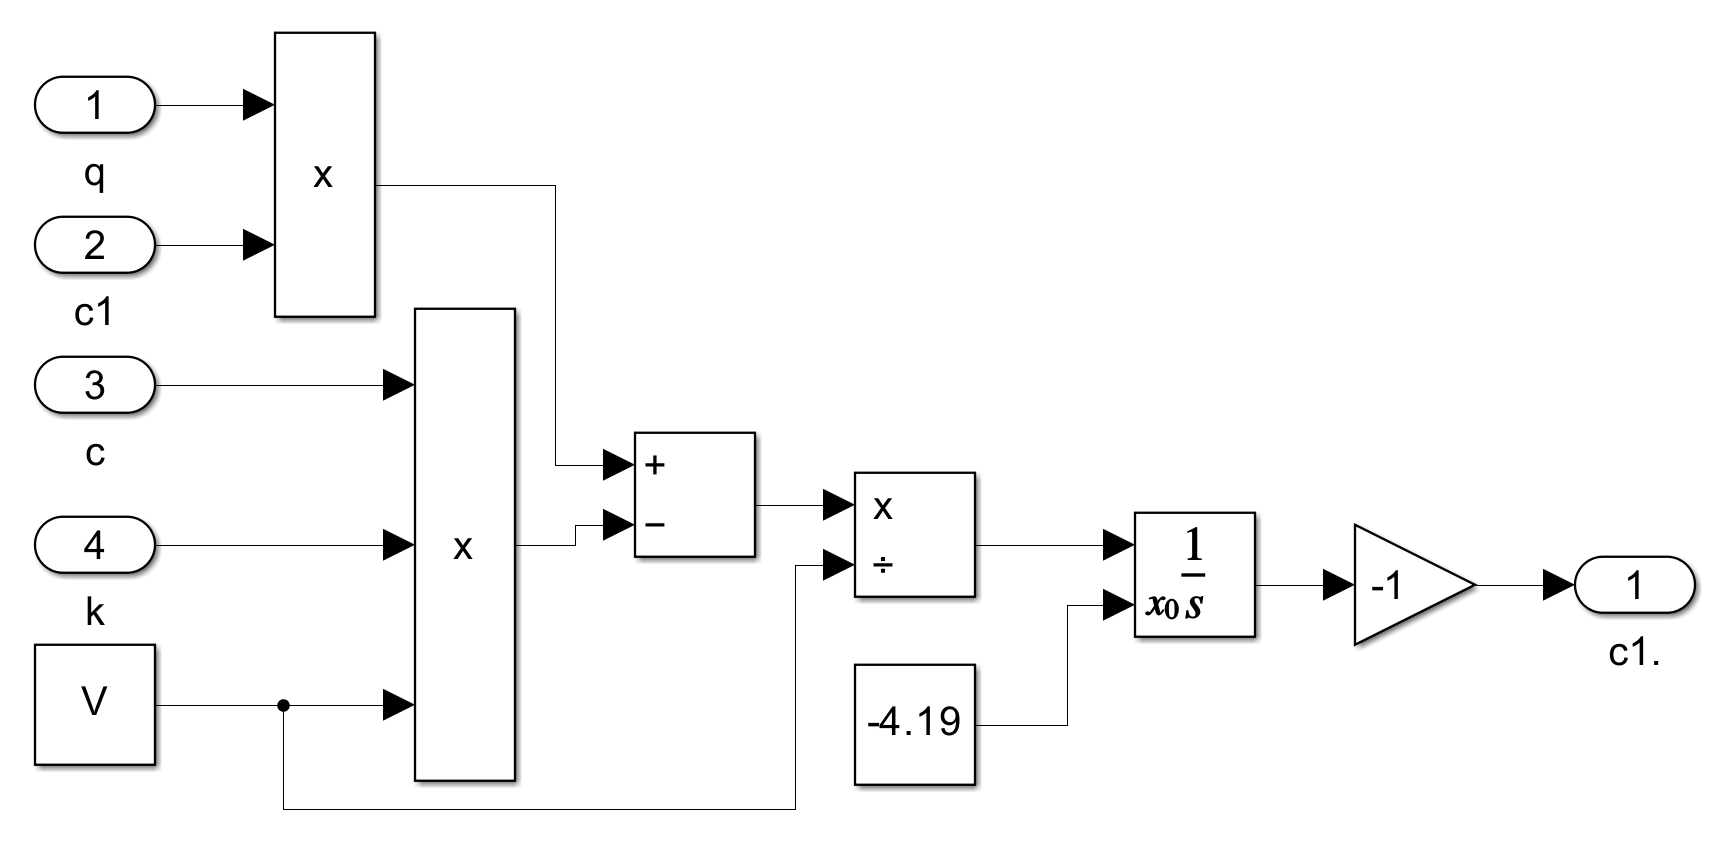

Daca simulam sistemul cu datele initiale, observam ca valoarea stationara a concentratiei reactantului este aproximativ 9.32 kmol/m3.

cis = 9.328; % valoarea stationara a concentratiei reactantului [kmol/m3]
X = (ci-cis)/ci % coeficientul de conversie al reactantului in produs [%]

X = 0.0672

Pentru a creste rentabilitatea putem ori sa scadem debitul, ori sa crestem volumul. Am ales sa crestem volumul de 10 ori.

V = 100; % [m3]
cis = 5.811; % noua valoare stationara a concentratiei reactantului [kmol/m3]
X = (ci-cis)/ci % noul coeficient de conversie al reactantului in produs [%]

X = 0.4189

Facem identificarea functiilor de transfer:

5.811+0.632*(6.04-5.811)

ans = 5.9557

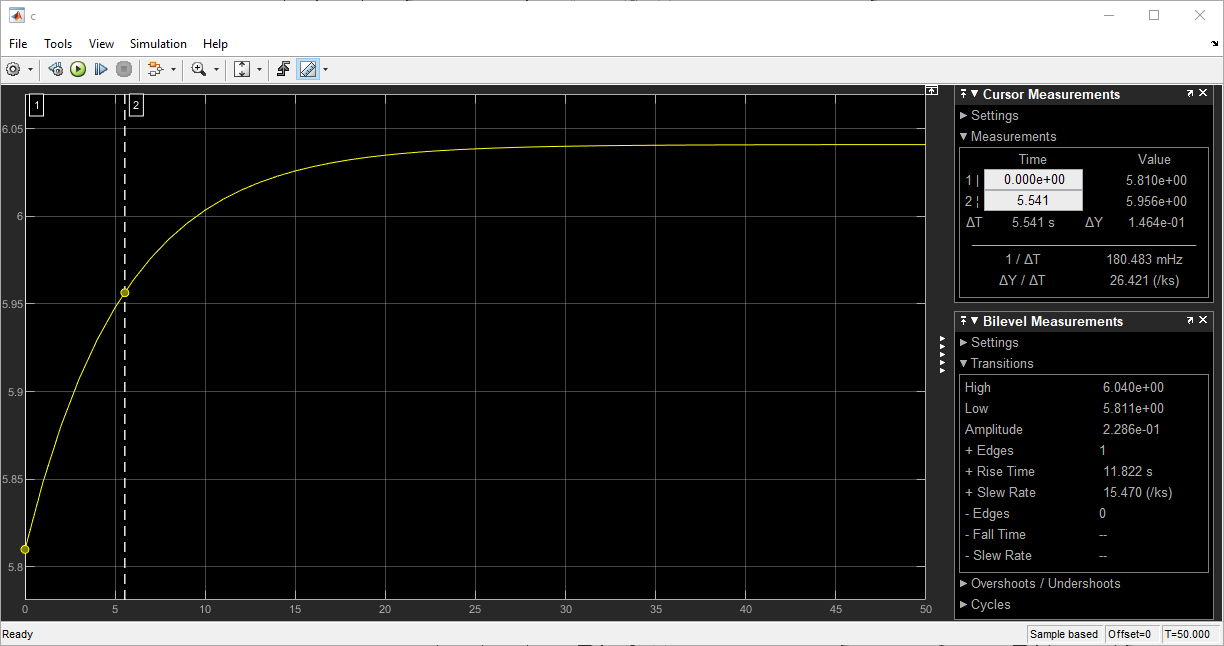

Hqc = tf((6.04-5.811)/11, [5.54, 1]); % functia de transfer de la q la c
4.189+0.632*(3.96-4.189)

ans = 4.0443

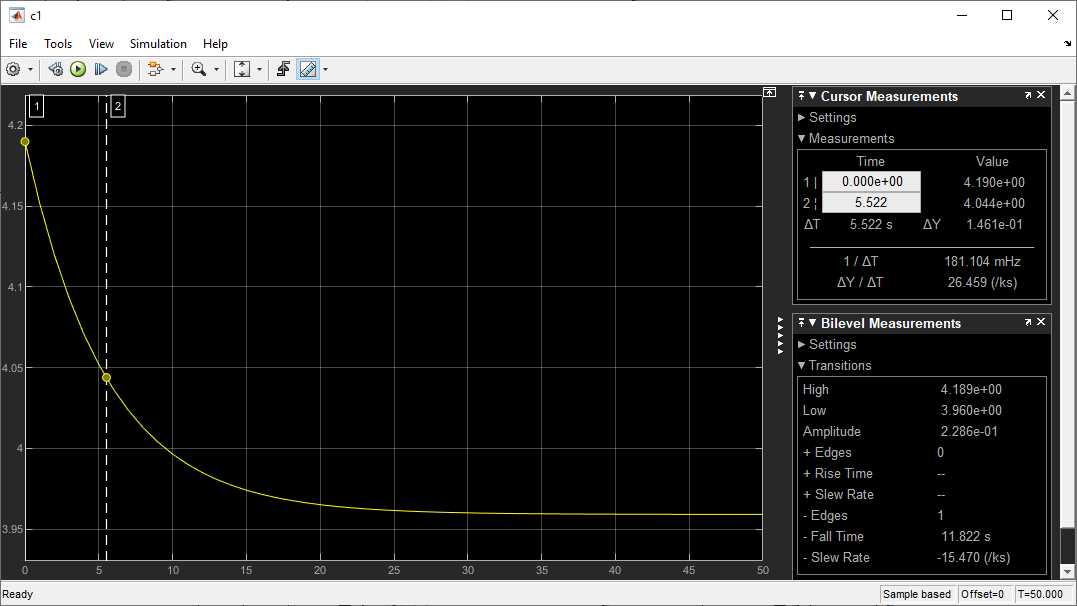

Hqc1 = tf((3.96-4.189)/11, [5.5, 1]); % functia de transfer de la q la c1
5.813+0.632*(6.389-5.813)

ans = 6.1770

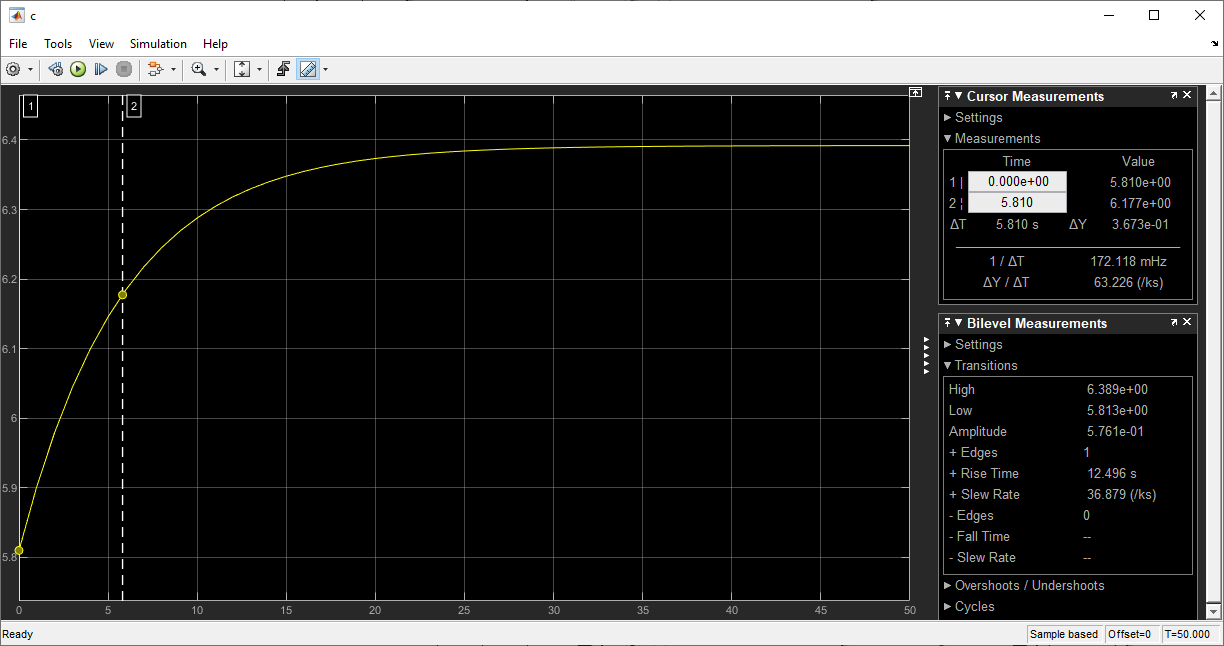

Hcic = tf((6.389-5.813)/11, [5.81, 1]); % functia de transfer de la ci la c
4.192+0.632*(4.595-4.192)

ans = 4.4467

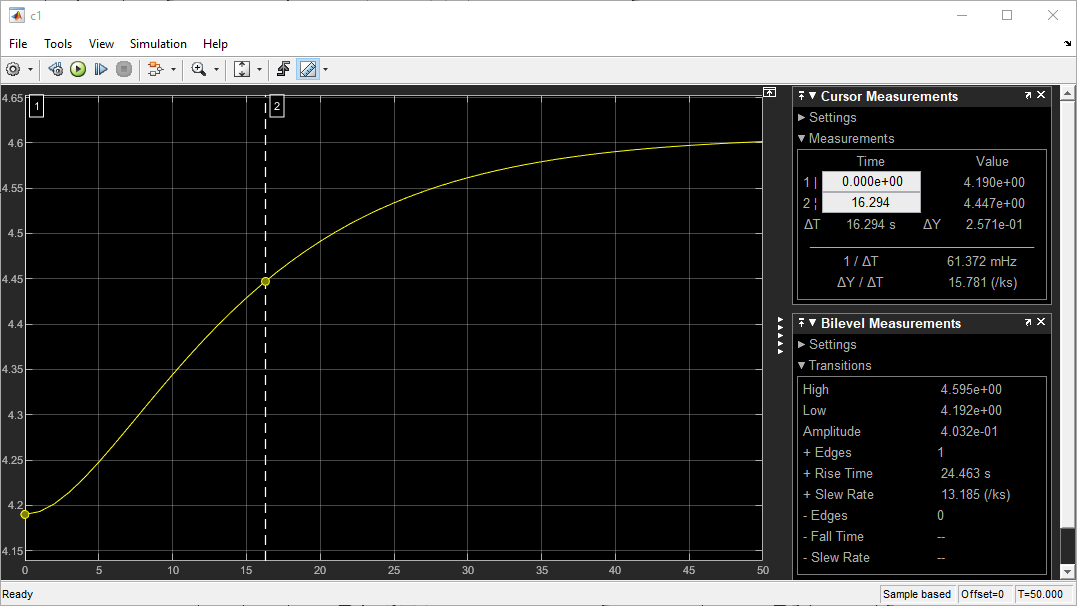

Hcic1 = tf((4.595-4.192)/11, [16.28, 1]); % functia de transfer de la ci la c1

Proiectam regulatorul prin impunerea unui raspuns corespunzator unei functii de gradul 1 in bucla inchisa si a unui timp de raspuns dorit.

Himpus = tf(1, [1 1]);
Hregulatorqc = Himpus/(Hqc*(1-Himpus));
Hregulator = minreal(Hregulatorqc);
Kp = Hregulator.num{1,1}(1);
Ki = Hregulator.num{1,1}(2);
Ti = 5.811;

Construim modelul de care avem nevoie in simulink:

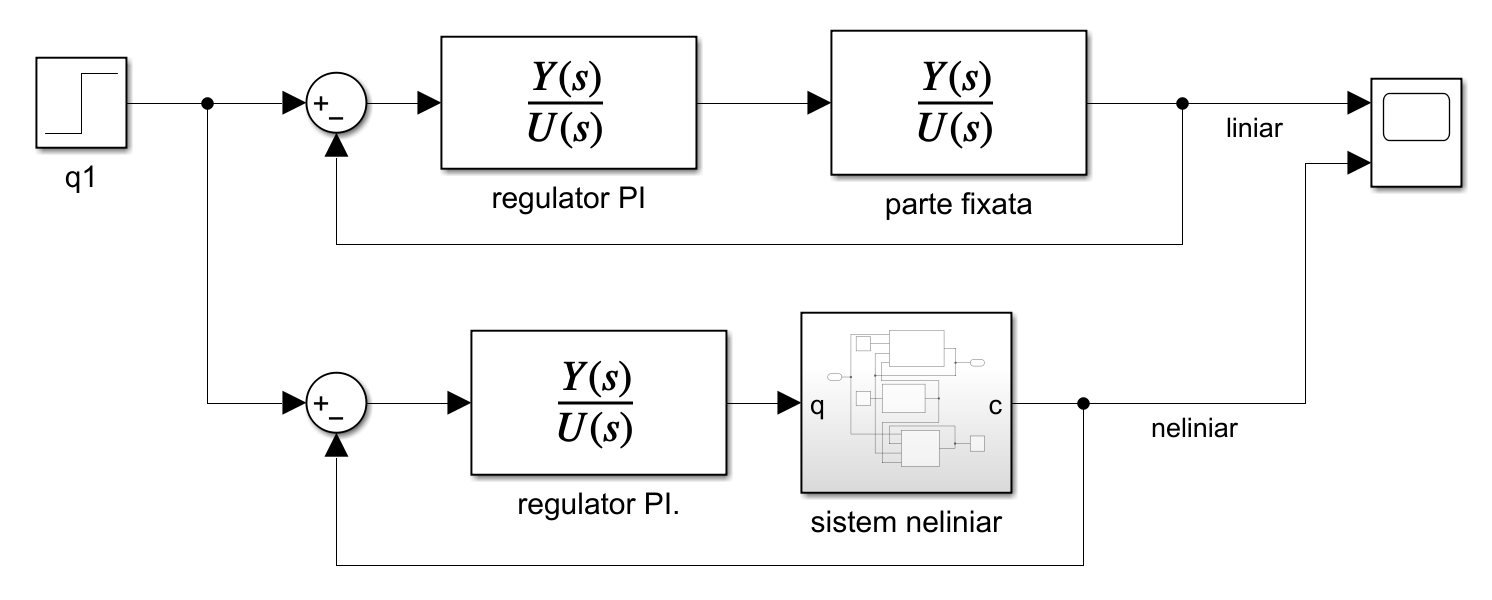

Rezultate:

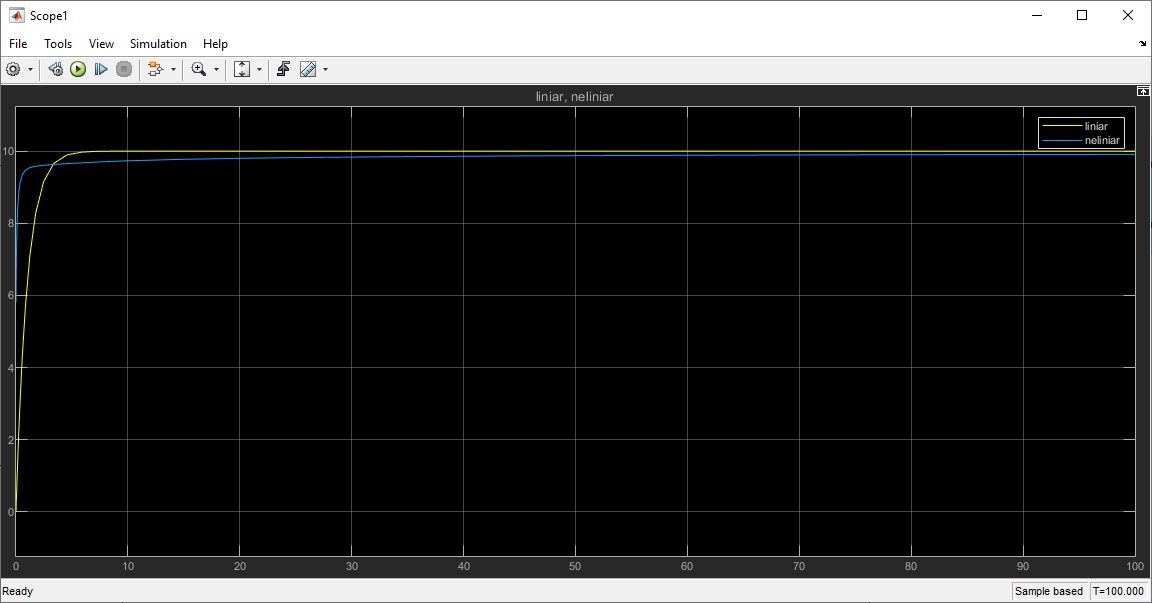

Functia RCCA:

function Xdot = RCCA(~,X)
c = X(1); T = X(2);
if (c<0)
    c = 0;
end
k0 = evalin('base','k0');
Edr = evalin('base','Edr');
q = evalin('base','q');
ci = evalin('base','ci');
V = evalin('base','V');
rcp = evalin('base','rcp');
Ti = evalin('base','Ti');
hA= evalin('base','hA');
Tr = evalin('base','Tr');
mdH = evalin('base','minusdeltaH');
k = k0*exp(-Edr/T);
cdot = (q*(ci-c)-V*k*c)/V;
Tdot = (rcp*q*(Ti-T)+hA*(Tr-T)+mdH*V*k*c)/(rcp*V);
Xdot = [cdot;Tdot];
end